# Parse sounding

**Warning: this script is outdated and has been replaced with the GUI. It will run, but is not necessary for the simulation environment. It is left here in case the need arises to parse an entire station file to extract all soundings, and because it demonstrates some of the extra functionality supported by the IGRA parser not used by the environment.**

This script parses a derived parameter file, filters out soundings missing necessary information, chooses one sounding, extracts only the data needed for the Simulink model and plots it. 

## Parse and filter soundings

% Only do this once per file.

% Choose a file
filename = 'IGRA-Parser/Stations/GMM00010962-drvd.txt';

% Parse derived parameter file (this takes a few minutes)
soundings = parse_derived(filename);

% Filter soundings based on the presence of the mixed layer height parameter
soundings = filter_soundings(soundings);

## Choose one sounding

sounding_number = 11; % choose the sounding you want

% Extract and return only the relevant data in the chosen sounding
reduced_sounding = extract_sounding_data(soundings(sounding_number));

Extracted and sanitized sounding data



% Remove all measurements that have a geopotential height REPGPH
% greater than 1.3 times the mixed layer height.
reduced_sounding = remove_values_above(reduced_sounding, 10000);

max_height interpreted as a direct height value



% Interpolate missing values in the reduced sounding
reduced_sounding = interpolate_missing(reduced_sounding);

Interpolated missing values in 1 meter intervals



% Save this sounding to the workspace for future use
save('sounding.mat', 'reduced_sounding');

## Plot atmospheric profiles

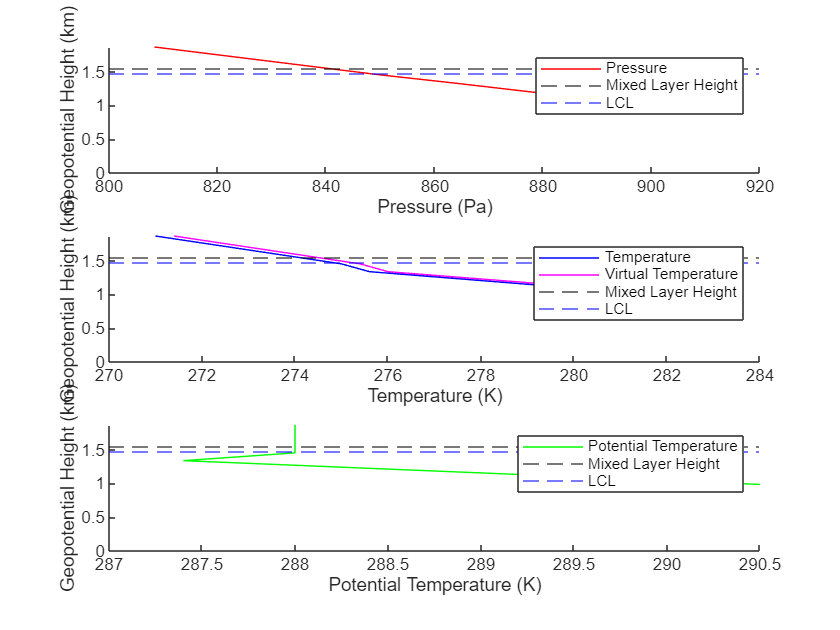

% Plot pressure, temperature, potential temperature and virtual 
% temperature profiles over geopotential height. The geopotential 
% height is used as the vertical coordinate.
plot_sounding(reduced_sounding,2); % second argument is optional